clear all;

% Original Matirx
G = [255 255 255 255 255 255 255 255 
255 255 255 100 100 100 255 255; 
255 255 100 150 150 150 100 255; 
255 255 100 150 200 150 100 255; 
255 255 100 150 150 150 100 255; 
255 255 255 100 100 100 255 255 
255 255 255 255 50 255 255 255; 
50 50 50 50 255 255 255 255];

[U,S,V]=svd(G); % Using Matlab function

% Implementing svd from scratch
n = size(G,1);
G_copy = G;
[curr_s, curr_v] = power_iter(G);
curr_v = curr_v/norm(curr_v);
curr_u = G_copy*curr_v/curr_s;
ans_v = curr_v;
ans_u = curr_u;
ans_s = curr_s;
for i=1:n-1
    update_G = G_copy - curr_s*curr_u*(curr_v)';
    [update_eigen,update_v] = power_iter(update_G);
    update_u = update_G*update_v/update_eigen;
    update_v = update_v/norm(update_v);
    ans_u = [ans_u update_u];
    ans_v = [ans_v update_v];
    ans_s = [ans_s update_eigen];
    curr_u = update_u;
    curr_v = update_v;
    curr_s = update_eigen;
    G_copy = update_G;
end
ans_s = diag(ans_s);
diff = norm(ans_s-S)

diff = 1.6259e-07

% Reconstruction of approximate images using largest eigenvalues
img1 = ans_u(:,1)*ans_s(1,1)*ans_v(:,1)';
img2 = ans_u(:,1:2)*ans_s(1:2,1:2)*ans_v(:,1:2)';
img3 = ans_u(:,1:3)*ans_s(1:3,1:3)*ans_v(:,1:3)';
img4 = ans_u(:,1:4)*ans_s(1:4,1:4)*ans_v(:,1:4)';
img5 = ans_u(:,1:5)*ans_s(1:5,1:5)*ans_v(:,1:5)';

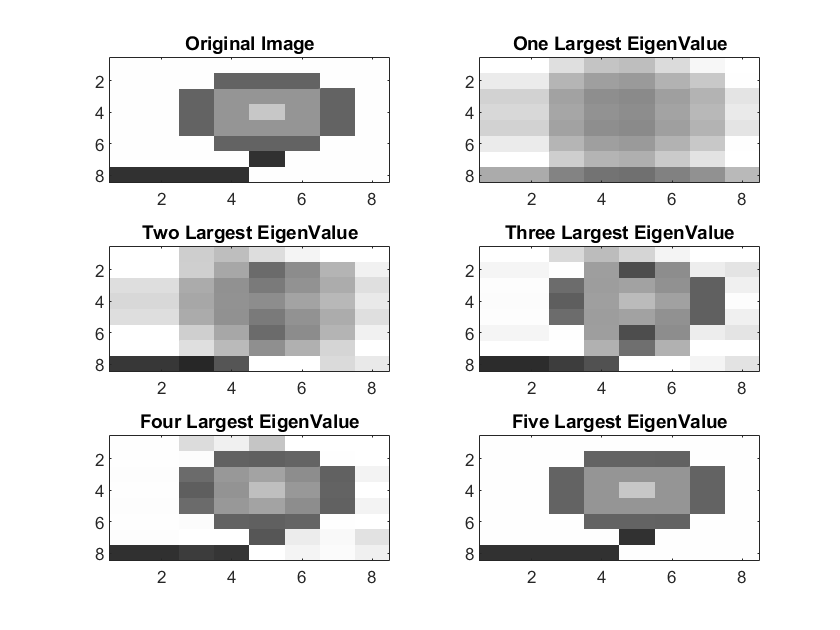

% Plotting the approximate reconstructed images
figure;
subplot(3,2,1);
image(G);
colormap("gray");
title("Original Image");

subplot(3,2,2);
image(img1);
colormap("gray");
title("One Largest EigenValue");

subplot(3,2,3);
image(img2);
colormap("gray");
title("Two Largest EigenValue");

subplot(3,2,4);
image(img3);
colormap("gray");
title("Three Largest EigenValue");

subplot(3,2,5);
image(img4);
colormap("gray");
title("Four Largest EigenValue");

subplot(3,2,6);
image(img5);
colormap("gray");
title("Five Largest EigenValue");

% Getting norm of the difference the original image and reconstructed
% images
dist1=norm(G-img1)

dist1 = 334.0981

dist2=norm(G-img2)

dist2 = 267.8401

dist3=norm(G-img3)

dist3 = 186.5231

dist4=norm(G-img4)

dist4 = 109.0080

dist5=norm(G-img5)

dist5 = 2.5886e-13

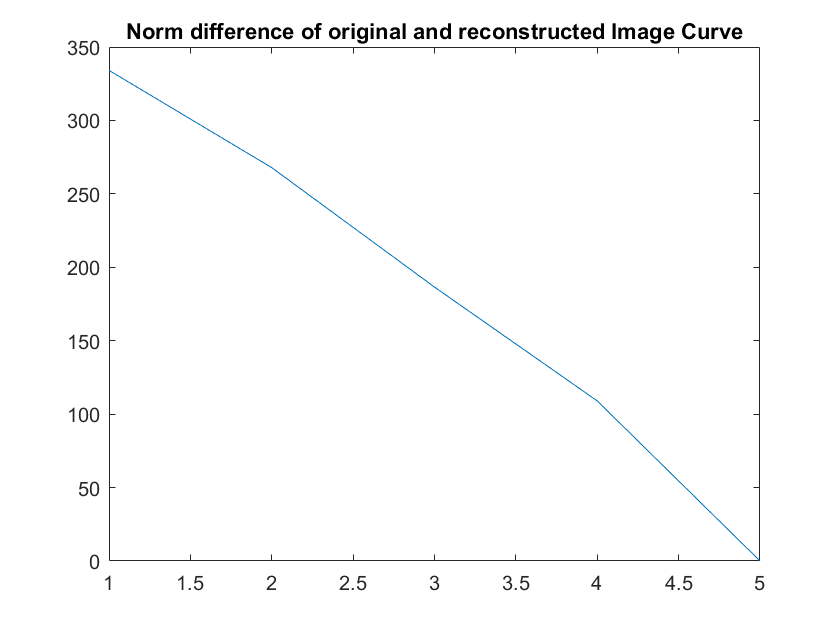

dist=[dist1 dist2 dist3 dist4 dist5];
figure;
plot(dist);
title("Norm difference of original and reconstructed Image Curve");

function[eigen_value,eigen_vector] = power_iter(G)
    n = size(G,1);
    v = ones(n,1);
    G = (G)'*G;
    val = v\G*v;
    while true
        v_update = G*v/norm(G*v);
        val_update = v_update\G*v_update;
        if(abs(val-val_update)<0.0001)
            break
        end
        v = v_update;
        val = val_update;
    end
    eigen_value = sqrt(val);
    eigen_vector = v;
end